# RLSフィルタ比較

fsize = 5000;    %フレームサイズ
FF = 0.98;
Ni = 50;
lengthF = 5;
lengthInit = 10;
Avgi = 30;
avgt = zeros(Avgi,1);
rlst = zeros(Ni,1);
graphF = false;

mode = true; % true = white noise
             % false = pink noise

## RLSフィルタ設計

フィルタのタップ数を変更

for i = 1:Ni
    fleng = lengthInit + i * lengthF;
    strFF = '''ForgettingFactor''';
    eval(['rlsfilt',num2str(i),' = dsp.RLSFilter(fleng,', strFF, ', FF);']);
end

## ノイズ

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
dp = Hp();

Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
dw = Hw();

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

xp = firfilt(dp);
xw = firfilt(dw);

if graphF == true
    
    for i = 1:Ni
        eval(['TS',num2str(Ni),' = dsp.TimeScope(','''TimeSpan''',',1.1*fsize,',...
            '''TimeUnits''',',','''Seconds''',',','''YLimits''',...
            ',[-3 3],','''BufferLength''',',4*fsize,','''ShowLegend''',...
            ',true,','''ChannelNames''',', {','''Noisy signal''',',', '''err''','},',...
            '''Title''',',''',num2str(Ni),''');']);
    end
    
end


% TSe = dsp.TimeScope('TimeSpan',1.1*fsize,'TimeUnits','Seconds',...
%     'YLimits',[-3 3],'BufferLength',4*fsize, ...
%     'ShowLegend',true,'ChannelNames', ...
%     {'LMS', 'NLMS', 'AP', 'RLS'},'Title','Err');

## ホワイトノイズ

if mode == true
    for i = 1:Ni
        for j = 1:Avgi
            tic;
            eval(['[~,e',num2str(i),'] = rlsfilt',num2str(i),'(dw,xw);']);
            avgt(j) = toc;
            eval(['rlsfilt',num2str(i),'.reset;']);
        end
        rlst(i) = mean(avgt);
        if graphF == true
            eval(['TS',num2str(i),'([xw,e',num2str(i),']);'])
        end
    end
end



## ピンクノイズ

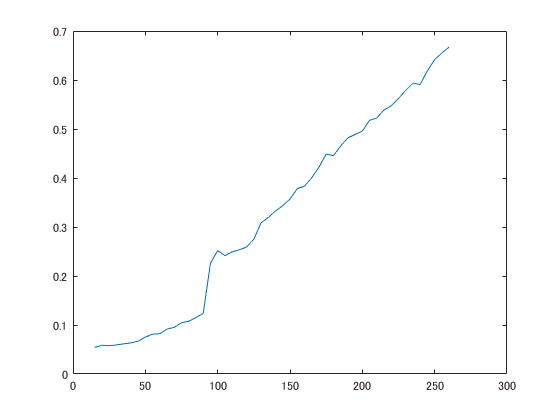

if mode == false
    for i = 1:Ni
        tic;
        eval(['[~,e',num2str(i),'] = rlsfilt',num2str(i),'(dp,xp);']);
        rlst(i) = toc;
        
        if graphF == true
            eval(['TS',num2str(i),'([xp,e',num2str(i),']);'])
        end
    end
end
plot(lengthF+lengthInit:lengthF:fleng,rlst);